vecSniff = [audioClipObjSniff.getCurrentVec;0];
vecAudio = audioClipObj.getCurrentVec;
szSniff = numel(vecSniff);
szAudio = numel(vecAudio);


vecSniffResampled =resample(vecSniff,250000,5000);

% figure
% cwt(vecSniffResampled,2.5e5)

% figure
% cwt(vecAudio,2.5e5)


wtSniff = cwt(vecSniffResampled,2.5e5);
wtAudio = cwt(vecAudio,2.5e5);
diffAudio = (wtAudio-wtSniff);
cleanAudio = icwt(diffAudio);

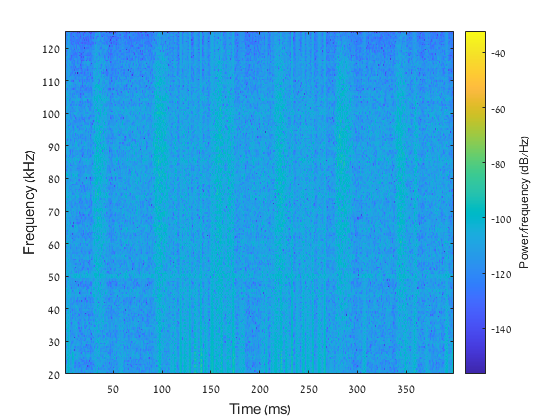

figure
spectrogram(cleanAudio,512,[],[],2.5e5,'yaxis');

ylim([20 inf])

ax = gca

ax =   Axes with properties:

             XLim: [0.512 398.85]
             YLim: [20 Inf]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.11638 0.11 0.69381 0.815]
            Units: 'normalized'

  Show all properties


ax.CLim

ans =       -156.54       -32.23


% ax.CLim = [-100 -30]